# Simulación sistema solar

## Introducción

El objetivo de este código es modelar el comportamiento del Sistema Solar de manera parcial en diferentes casos. 

El primer caso será un modelo entre la Tierra y la Luna; el segundo, uno entre el Sol, la Tierra y Venus; y el tercero, uno entre el Sol, la Tierra y la Luna.

A la vez, se buscará la generalización del método creado para solucionar problemas de valor inicial (IVPS) para su posterior aplicación.

## Marco Teórico

La constante de la gravitación universal es una constante física que mide la fuerza de atracción gravitatoria entre los cuerpos. Esta constante sale de la ley de la gravitación universal, la cual establece que: La interacción gravitatoria entre dos cuerpos puede expresarse mediante una fuerza directamente proporcional al producto de las masas de los  cuerpos e inversamente proporcional al cuadrado de la distancia que los separa. Por lo mismo, se puede expresar siguiendo la fórmula a continuación presentada (Figura 1.1).


$$F\;=\;\frac{G*\mathrm{m1}*\mathrm{m2}}{r^2 }$$
 

La fuerza centípeta es la representación de la fuerza ejercida por un cuerpo que está en movimiento sobre un camino curvo hacia el centro de la curvatura del camino. Esta fuerza es directamente proporcional a la velocidad del objeto y su masa e inversamente proporcional a su radio; siendo de esta manera entonces que se puede expresar siguiendo la fórmula a continuación presentada (Figura 1.2).


$$F=\;\frac{m*v^2 }{r}$$


La velocidad angular es la representación del tiempo que tarda en girar un objeto sobre un ángulo. Esta velocidad es directamente proporcional a la velocidad normal de un objeto e inversamente propocional al periodo y al radio; por ello, se expresa siguiendo la fórmula a continuación presentada (Figura 1.2).

$\mathrm{Ws}\;=\;\frac{v}{r}$           o de la misma manera           $\mathrm{Ws}\;=\;\frac{2*\pi }{T}$

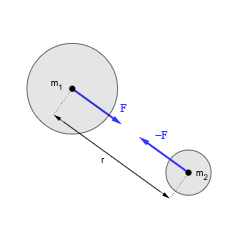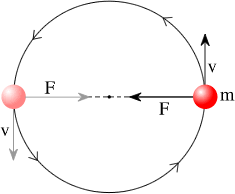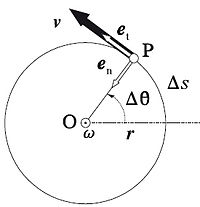

                   Figura 1.1                                            Figura 1.2                                      Figura 1.3

## Convenciones

Para los modelos que serán presentados a continuación, se considerará a los cuerpo celeste como cuerpos puntuales (no como cuerpos extensos).

Se expresará la posición de los cuerpos celestes en un vector de 3 filas y una columna que contenga las coordenadas x,y,z en las posiciones 1, 2 y 3 respectivamente.

Para nombrar las variables, se usaran las iniciales de las palabras que lo compongan; por ejemplo, para nombrar la masa de la tierra, se declarará a la variable como mT, o el radio de venus, rV.

La constante de gravitación universal que será utilizada en este proyecto se verá representada por la letra G y será la especificada por la teoría de la gravitación de Newton.

Las orbitas de los planetas serán representadas como circulos perfectos en los modelos y por lo mismo, su velocidad anguar será la misma en todo punto.

Todas las masas están en kilogramos y todas las distancias en metros.

## Funciones utilizadas

# Presentación de los modelos

## Declaración de variables generales.

global G m;
G = 6.67408E-11;
mT = 5.9736E+24;
mV = 4.8670e+24;
mL = 7.3490e+22;
mS = 1.9890e+30;
rT = 6.371e+6;
%rV = 6.0518e+6;
%rL = 1.7371e+6;
rS = 6.957e+8;
dTL = 3.84400e+8;
dST = 1.496e+11;
dSV = 1.082e+11;
%dSL
h = 60;              
nv = 4;

## Modelo Tierra y Luna

En este modelo, la tierra estará en el origen al inicio, ya que se verá influenciada por la atracción de la Luna posteriormente.

Los vectores que se utilizarán seguirán el modelo [Tierra, Luna].

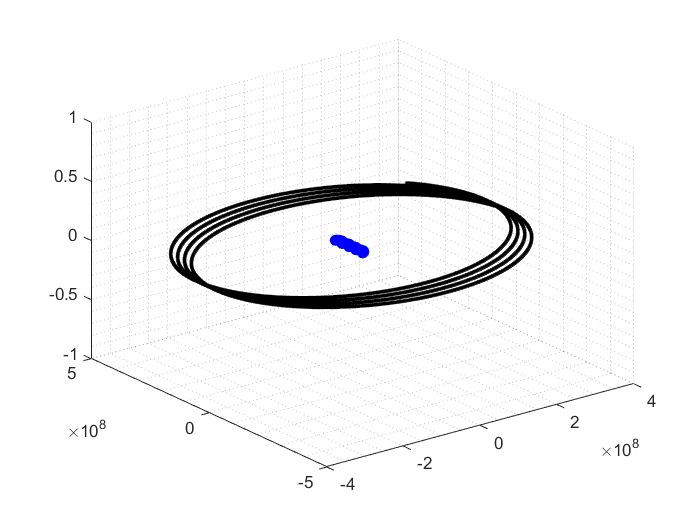

m = [mT, mL];
r0 = [ [0;0;0], [rT+dTL;0;0] ];
vs = sqrt(G * m(1)/r0(1,2));
v0 = [ [0;0;0], [0;vs;0] ];
ws = vs/(rT+dTL);
T = (2*pi)/ws;
Nk = nv*ceil(T/h);
pos = zeros(6,Nk+1);
pos(:,1) = [r0(:,1);r0(:,2)];
y = [r0;v0];

for t=2:Nk+1
  s1 = fSistSol(t,y);
  s2 = fSistSol(t+h/2,y+(h/2)*s1);
  s3 = fSistSol(t+h/2,y+(h/2)*s2);
  s4 = fSistSol(t+h, y+h*s3);
  slope = (s1+2*s2+2*s3+s4)/6;
  y = y + slope*h;
  r = y(1:3,:); 
  pos(:,t) = [r(:,1);r(:,2)];         
end

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.k');
grid minor;

## Modelo Sol, Tierra y Venus

En este modelo, el Sol estará en el origen al inicio, ya que se verá influenciado por la atracción de la Tierra y Venus posteriormente.

Los vectores que se utilizarán seguirán el modelo [Sol, Tierra, Venus].

## Modelo Sol, Tierra y Luna

En este modelo, el Sol estará en el origen al inicio, ya que se verá influenciado por la atracción de la Tierra y de la Luna posteriormente.

Los vectores que se utilizarán seguirán el modelo [Sol, Tierra, Luna].

## Generalización IVPS

# Fuentes

[1] Antonio, M. (2000). Historia y epistemología de las ciencias. Universidad complutense de Madrid, 18 (2), pp 319-332.

[2] Serway, R., Jewett, J. and Peroomian, V. (n.d.). Physics for scientists and engineers. 6th ed.

[3] Bibing.us.es. (2019). Servicio por satélite. [online] Available at: http://bibing.us.es/proyectos/abreproy/12114/fichero/Memoria%252FMemoria.pdf [Accessed 8 May 2019].

[4] Jaespimon.wordpress.com. (2019). gravitación | COSAS DE CIENCIA... Física y Química. [online] Available at: https://jaespimon.wordpress.com/tag/gravitacion/ [Accessed 8 May 2019].

[5] Olmos, M. (2019). Fuerza Centrípeta. [online] Hyperphysics.phy-astr.gsu.edu. Available at: http://hyperphysics.phy-astr.gsu.edu/hbasees/cf.html [Accessed 8 May 2019].

[6] Tipler, P. and Mosca, G. (2010). Física para la ciencia y la tecnología. 1st ed. Barcelona: Reverté.